clear all

% Environment
environment.gravity = 9.81; % m/s^2
[sX,sY,sZ] = sphere();
rad = 6371e3;
seed = [unifrnd(-1,1), unifrnd(-1,1), unifrnd(-1,1)];
seed = seed / norm(seed);

% Spacecraft
spacecraft.position = unifrnd(5, 7) * rad .* seed; % Initial position
spacecraft.velocity = 500 * [unifrnd(-5,5), unifrnd(-5,5), unifrnd(-5,5)]; % Initial velocity
spacecraft.acceleration = [0, 0, 0]; % Initial acceleration
spacecraft.orientation = [1, 0, 0, 0]; % Initial quaternion
spacecraft.state = [spacecraft.position, spacecraft.velocity, spacecraft.acceleration, spacecraft.orientation]

spacecraft = struct with fields:
        position: [-3.6745e+07 -1.5199e+06 1.6984e+07]
        velocity: [-522.4239 -662.8168 2.4399e+03]
    acceleration: [0 0 0]
     orientation: [1 0 0 0]
           state: [-3.6745e+07 -1.5199e+06 1.6984e+07 -522.4239 -662.8168 2.4399e+03 0 0 0 1 0 0 0]


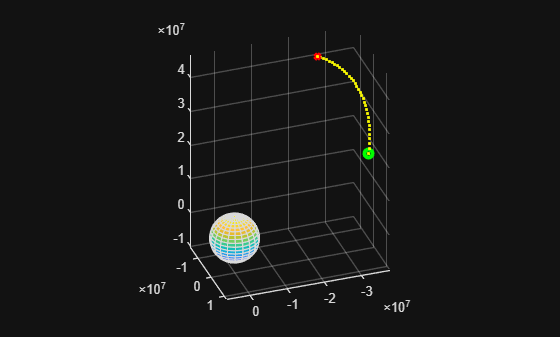

spacecraft.trajectory = [spacecraft.position];

% Propagation
time.duration = 1000000;
time.step = 500;
time.mesh = 0 : time.step : time.duration;
time.meshSize = length(time.mesh);
verletTraj = zeros(time.meshSize,3);
verletVel = verletTraj;

figure(1);
hold on
surf(rad*sX,rad*sY,rad*sZ);
craft = plot3(spacecraft.position(1), spacecraft.position(2), spacecraft.position(3), 'rx', 'LineWidth', 3);
start = plot3(spacecraft.position(1), spacecraft.position(2), spacecraft.position(3), 'go', 'LineWidth', 3);
path = plot3(spacecraft.trajectory(:,1), spacecraft.trajectory(:,2), spacecraft.trajectory(:,3), 'y.', 'LineWidth', 0.01);
axis equal
%xlim([-5e7, 5e7])
%ylim([-5e7, 5e7])
%zlim([-5e7, 5e7])
grid on
updateCamera = spacecraft.position;
view([updateCamera(1), updateCamera(2), updateCamera(3)]);


for t = 1:time.meshSize

    verletTraj(t,:) = spacecraft.position;
    verletVel(t,:) = spacecraft.velocity;
    spacecraft.trajectory(mod(t,round(length(time.mesh)/10)) + 1, :) = [spacecraft.position];

    craft.XDataSource = 'spacecraft.position(:,1)';
    craft.YDataSource = 'spacecraft.position(:,2)';
    craft.ZDataSource = 'spacecraft.position(:,3)';
    path.XDataSource = 'spacecraft.trajectory(:,1)';
    path.YDataSource = 'spacecraft.trajectory(:,2)';
    path.ZDataSource = 'spacecraft.trajectory(:,3)';
    refreshdata
    drawnow
    %updateCamera = 0.3 * updateCamera + 0.7 * spacecraft.position;
    view([sin(0.01*t), cos(0.01*t), 0.6]);
    pause(0.01)

    spacecraft.updatePosition = spacecraft.position + spacecraft.velocity * time.step + 0.5 * spacecraft.acceleration * (time.step ^ 2);
    if norm(spacecraft.updatePosition) < rad
        collisionFind = zeros(100,3);
        for i = 1:100
            collisionFind(i,:) = (1 - 1/i) * spacecraft.updatePosition + (1/i) * spacecraft.position;
            if norm(collisionFind(i,:)) <= rad
                spacecraft.updatePosition = collisionFind(i,:);
                break
            end
        end
        spacecraft.positionVect = spacecraft.updatePosition / norm(spacecraft.updatePosition);
        spacecraft.velocity = spacecraft.velocity - 2 * dot(spacecraft.velocity,spacecraft.positionVect) * spacecraft.positionVect;
    end
    spacecraft.position = spacecraft.updatePosition;

    % FORCES UPDATE
        dynamics.gravity = - (environment.gravity/(norm(spacecraft.position)/rad)^2) .* (spacecraft.position/norm(spacecraft.position));
        dynamics.moon = - 0 * environment.gravity .* ((spacecraft.position - [2, 2, 2]) / norm(spacecraft.position - [2, 2, 2]));
        if norm(spacecraft.position) ^ 2 < (3 * rad) ^ 2
            u = 0;%sqrt(-norm(spacecraft.position)^2 + (3*rad)^2);
            spacecraft.controlAccel = - u * [dynamics.gravity(1), dynamics.gravity(2), dynamics.gravity(3)];
        else
            spacecraft.controlAccel = [0, 0, 0];
        end
    spacecraft.newAcceleration  = dynamics.gravity + spacecraft.controlAccel + dynamics.moon;
    spacecraft.newVelocity = spacecraft.velocity + 0.5 * (spacecraft.acceleration + spacecraft.newAcceleration) * time.step;
    spacecraft.acceleration = spacecraft.newAcceleration;

    spacecraft.harmonic(mod(t,round(length(time.mesh)/10)) + 1, :) = (2 * norm(spacecraft.velocity) * norm(spacecraft.newVelocity))/(norm(spacecraft.velocity) + norm(spacecraft.newVelocity));
    spacecraft.velocity = spacecraft.newVelocity;
end


hold off